clear
addpath('E:\PhD\Adamantane_data\data')
addpath('E:\PhD\Anaconda2\ANACONDA_2\package\+smita\epicea')
addpath('E:\PhD\meetings_n_conf\2022\wk 14\Colormaps\Colormaps (5)\Colormaps')
Path = 'E:/PhD/meetings_n_conf/2022/wk 23/adamantane/';

S =data_list_adamantane;

## Transmission

% [centres,trans_function] = get_transmission_function(data_converted, data_stats);
epicea_2_scienta=load("epicea_2_scienta_raes.mat"); %transmission function

## data conversion

for f = 1: length(S)
    raw_data = IO.import_raw(S(f).dir_ada);
    mdata(f) = IO.import_metadata(S(f).dir_ada);
    data            = macro.filter(raw_data, mdata(f)); %define the multiplicity of events
    data_corrected = macro.correct(data, mdata(f));
    data_converted(f) = macro.convert(data_corrected, mdata(f));
    [data_stats(f)] =get_data_stats(data_converted(f));
    hv{f} = (S(f).label);
end

Log: Detector image translation correction performed on det1
Log: Detector image rotation correction performed on det1
Log: Radial angle-dependent correction performed on det1
Log: Detector image translation correction performed on det2
Log: Detector image rotation correction performed on det2
Log: delta TOF correction performed on det2
Log: Lens abberation correction performed on det2


Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: the convert macro called angle_p_corr_C2 failed to run on det2


The Scaling factor is 0.54513


Log: Detector image translation correction performed on det1
Log: Detector image rotation correction performed on det1
Log: Radial angle-dependent correction performed on det1
Log: Detector image translation correction performed on det2
Log: Detector image rotation correction performed on det2
Log: delta TOF correction performed on det2
Log: Lens abberation correction performed on det2


Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: the convert macro called angle_p_corr_C2 failed to run on det2


The Scaling factor is 0.48224


## Plot AES

%% Load REAS 287, 287.6 and 292.28

Shift_Scienta = -1.25 %eV

Shift_Scienta = -1.2500

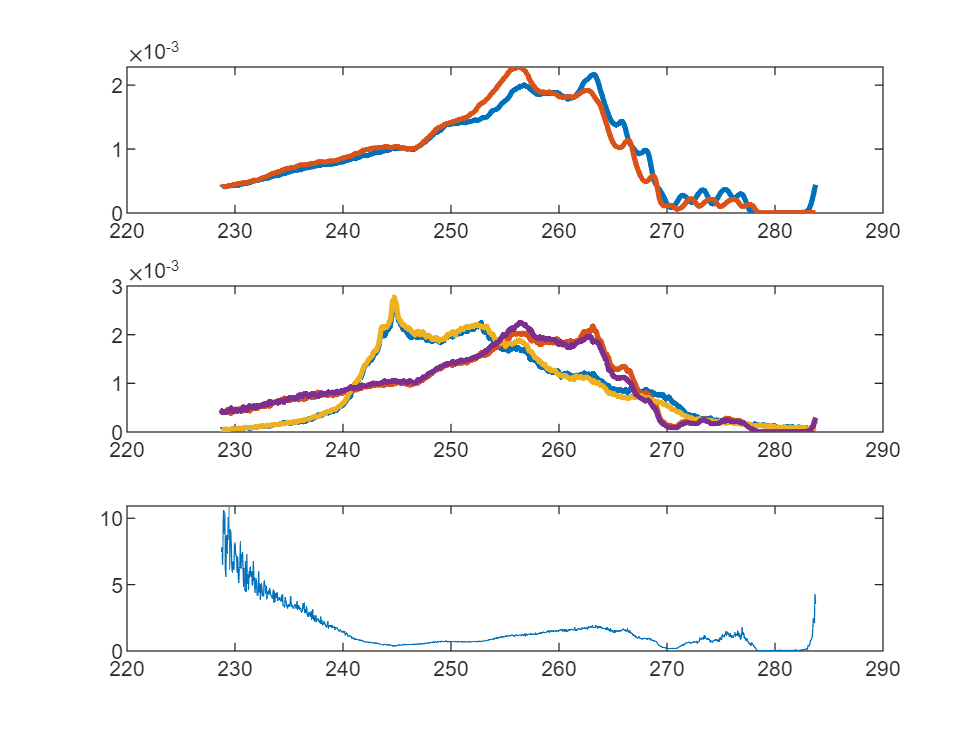


RAES_287 = dlmread([Path 'DATA/SCIENTA/Ada_res1_287eV_179.txt'],'',1,0);
RAES_287p6 = dlmread([Path 'DATA/SCIENTA/Ada_res2_287eV_180.txt'],'',1,0);

figure; subplot(3,1,1); 
hold on
plot(Shift_Scienta+RAES_287(:,1),smooth(RAES_287(:,2)./sum(RAES_287(:,2)),10),'LineWidth',2, 'DisplayName','SCIENTA RAES - CH')
plot((Shift_Scienta+RAES_287p6(:,1)),smooth(RAES_287p6(:,2)./sum(RAES_287p6(:,2)),10),'LineWidth',2,'DisplayName','SCIENTA RAES - CH_2')
box on;
for i=1: length(S)
    [centres, electron_KE] = get_AES(data_converted(i), data_stats(i),epicea_2_scienta);
end

## AES

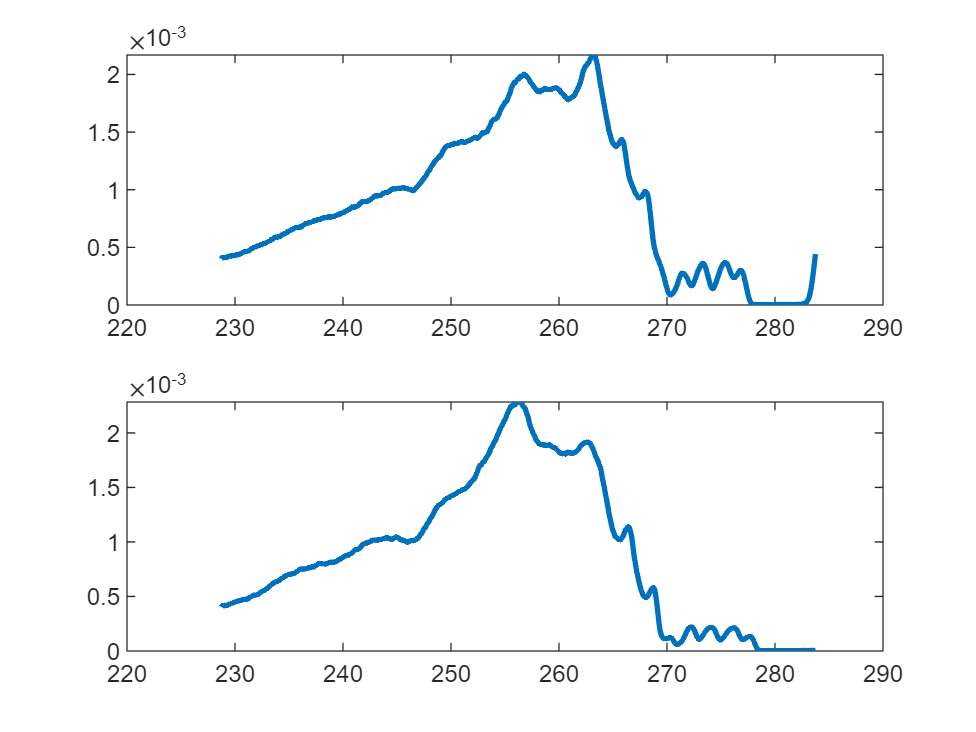

figure; subplot(2,1,1)
plot(Shift_Scienta+RAES_287(:,1),smooth(RAES_287(:,2)./sum(RAES_287(:,2)),10),'LineWidth',2, 'DisplayName','SCIENTA RAES - CH')
subplot(2,1,2)
plot((Shift_Scienta+RAES_287p6(:,1)),smooth(RAES_287p6(:,2)./sum(RAES_287p6(:,2)),10),'LineWidth',2,'DisplayName','SCIENTA RAES - CH_2')

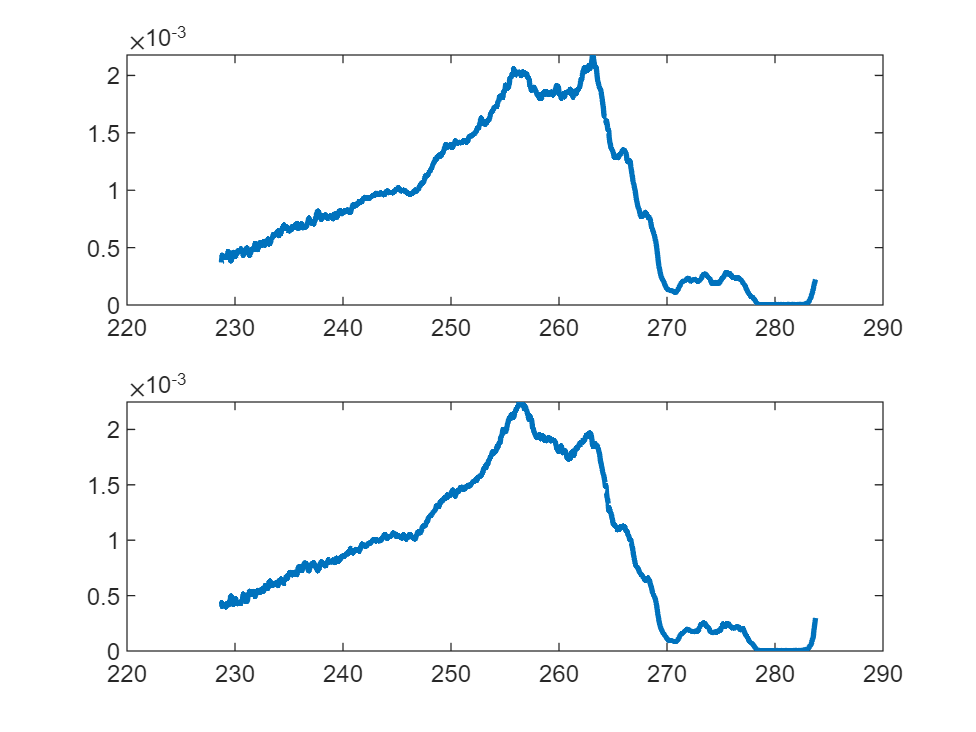

figure
for i=1: length(S)
    subplot(length(S),1,i)
    [centres, electron_KE] = get_AES(data_converted(i), data_stats(i),epicea_2_scienta);
end

## Ion TOF

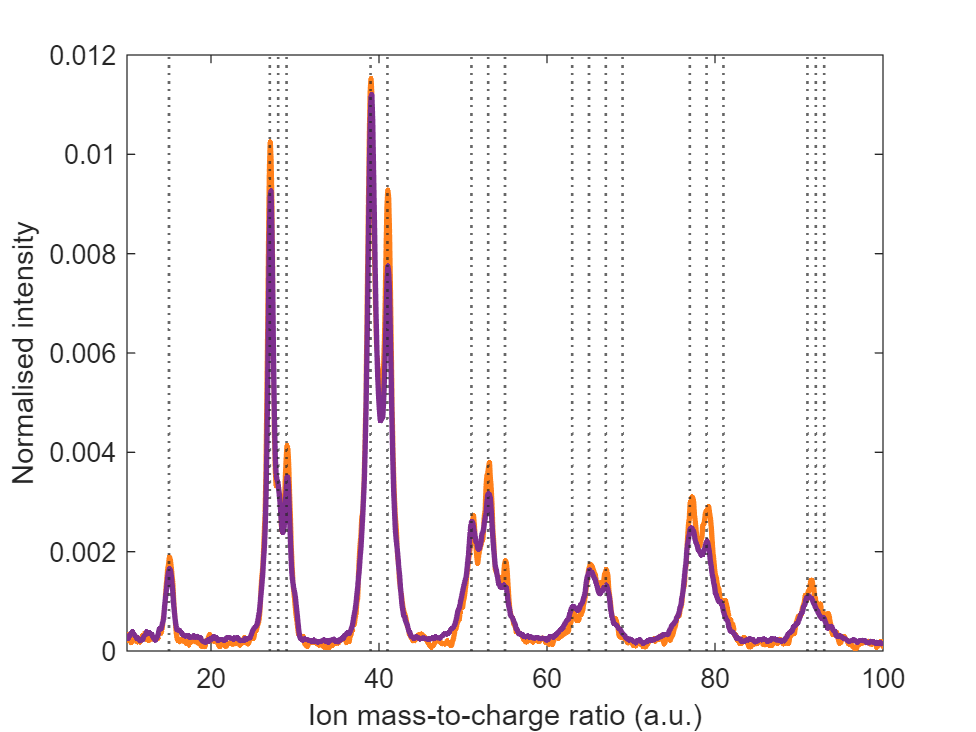

figure; hold on;
for i=1: length(S)
    plot_ion_m2q(data_converted(i), data_stats(i),S(i));
end
m2q_val=[15; 12*2+[3;4;5]; 12*3+[3;5]; 12*4+[3;5;7];12*5+[3;5;7;9];12*6+[5;7;9];12*7+[7;8;9] ];
for xx=1:length(m2q_val)
    xline(m2q_val(xx),':','LineWidth',1);
end
xlim([10 100])
box on
xlabel('Ion mass-to-charge ratio (a.u.)')
ylabel('Normalised intensity')